clear
close all
clc

L = [134.2 105.2 105.2 67.5];
off = [0 pi/2 -pi/2 0];
q1 = [0 0 0 0]*pi/180;
q2 = [40 23 42 40]*pi/180;
q3 = [72 -72 125 92]*pi/180;
q4 = [-88 48 -10 -43]*pi/180;
q5 = [-41 -69 86 -97]*pi/180;


Ln1 = Link('revolute', 'd', L(1), 'a', 0, 'alpha', pi/2, 'offset', off(1));
Ln2 = Link('revolute', 'd', 0, 'a', L(2), 'alpha', 0, 'offset',   off(2));
Ln3 = Link('revolute', 'd', 0, 'a', L(3), 'alpha', 0, 'offset',   off(3));
Ln4 = Link('revolute', 'd', 0, 'a', L(4), 'alpha', 0, 'offset',   off(4));

Eslab = [Ln1;Ln2;Ln3;Ln4];
T_tool = eye(4);
Robot1 = SerialLink(Eslab, 'tool', T_tool)

 
Robot1 = 
 
noname:: 4 axis, RRRR, stdDH, slowRNE                            
+---+-----------+-----------+-----------+-----------+-----------+
| j |     theta |         d |         a |     alpha |    offset |
+---+-----------+-----------+-----------+-----------+-----------+
|  1|         q1|      134.2|          0|     1.5708|          0|
|  2|         q2|          0|      105.2|          0|     1.5708|
|  3|         q3|          0|      105.2|          0|    -1.5708|
|  4|         q4|          0|       67.5|          0|          0|
+---+-----------+-----------+-----------+-----------+-----------+
 


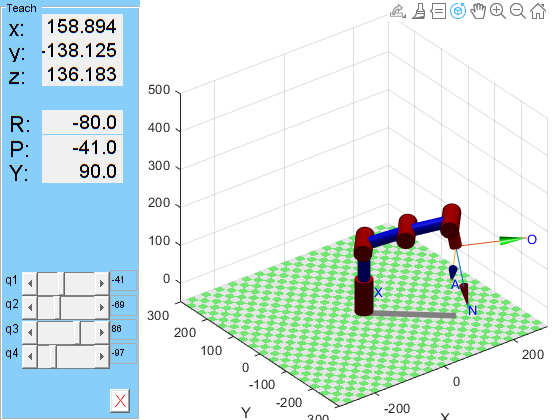



figure()
ws = [-300 300 -300 300 -50 500];
Robot1.plot ([0 0 0 0], 'workspace', ws, 'noa','noname')
hold on
trplot (eye(4), 'witdh', 2, 'arrow', 'length', 30)
Robot1.teach(q5) %% Usar el q que se desea de entre las opciones
hold off